# Modèle BAR (Erwan)

## Introduction : 

L'Objectif de ce modèle est de calculer une raideur anti-roulis permettant de maximiser l'adhérence du véhicule en virage. On veut donc maximiser l'adhérence des 4 pneus. 

- Plus le pneu est chargé, plus il adhère, mais le coefficient d'adhérence diminue.

- Les roues intéreieures au virage sont déchargées alors que les roues extérieures au virage se chargent.

Dans un premier temps, on essaye d'avoir la même charge sur les deux roues extérieures. (0/50 à l'avant et à l'arrière)

% modèle de barre anti-roulis

% Données
W=300;
KphiR=29.7;% en N/mm
KphiF=36.6;
l=1575;
tF=1295;
tR=1220;
WF=0.48*300;
WR=0.52*300;
h=300;
H=300;
b=l/(1+WR/WF);
a=l-b;
ZRR=50.67;
ZRF=36.44;

% Pour le skid pad avec notre cdc
t=5;
R=(15.25+3)/2;
v=2*pi*R/t;
A=(v^2/R)/9.81;

% Calcul des transferts de charge avant et arrière
dWF=A*(W/tF)*(H*KphiF/(KphiF+KphiR)+b*ZRF/l);
dWR=A*(W/tR)*(H*KphiR/(KphiF+KphiR)+a*ZRR/l);
WFO=WF/2+dWF

WFO = 134.3058

WFI=WF/2-dWF

WFI = 9.6942

WRO=WR/2+dWR

WRO = 136.0580

WRI=WR/2-dWR

WRI = 19.9420


% En rajoutant une raideur anti-roulis
Kav=2.47

Kav = 2.4700

dWF=A*(W/tF)*(H*(KphiF+Kav)/(KphiF+Kav+KphiR)+b*ZRF/l)

dWF = 63.9482

dWR=A*(W/tR)*(H*KphiR/(KphiF+Kav+KphiR)+a*ZRR/l)

dWR = 56.3146

WFO=(WF/2+dWF)/W

WFO = 0.4532

WFI=(WF/2-dWF)/W

WFI = 0.0268

WRO=(WR/2+dWR)/W

WRO = 0.4477

WRI=(WR/2-dWR)/W

WRI = 0.0723

On obtient 3/45 à l'avant et 7/45 à l'arrière. A priori on peut pas faire mieux car on n'a pas la même répartition de charge statique entre l'avant et l'arrière. 

Pour la suite, on travaille avec les efforts. On cherche une raideur telle que les résultantes latérales avant et arrière sont égales.

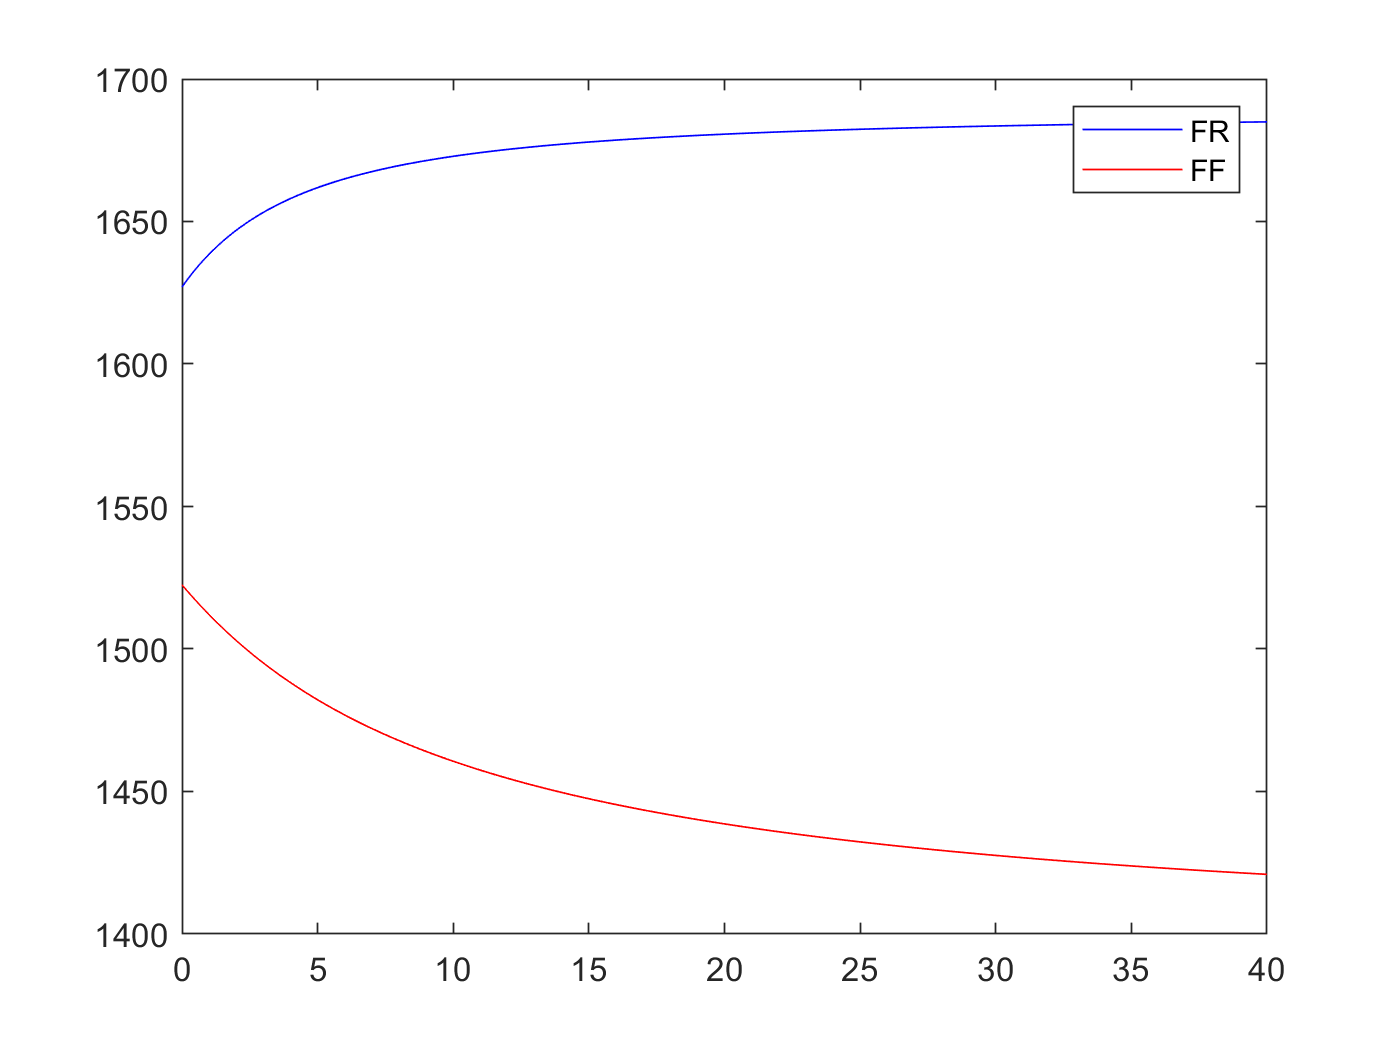

Kav= [0:0.1:40];
n=length(Kav);
Kar=zeros(1,n);
% Pour le skid pad avec notre cdc
t=5;
R=(15.25+3)/2;
v=2*pi*R/t;
A=(v^2/R)/9.81;
A=1.05;
F=force_lat(Kav,Kar,A);
FR=F(1:401);
FF=F(402:802);
plot(Kav,FR,'b',Kav,FF,'r')
legend('FR','FF')

On a une égalisation des résultantes avant et arrières pour une raideur KB=17.2 N/m.

On fait varier l'accélération en gardant notre raideur de 17.2 N.m pour trouver l'accélération max. On trouve 1.1g.

Puis optimisation en faisant varier la raideur KB pour faire décrocher les deux en même temps.

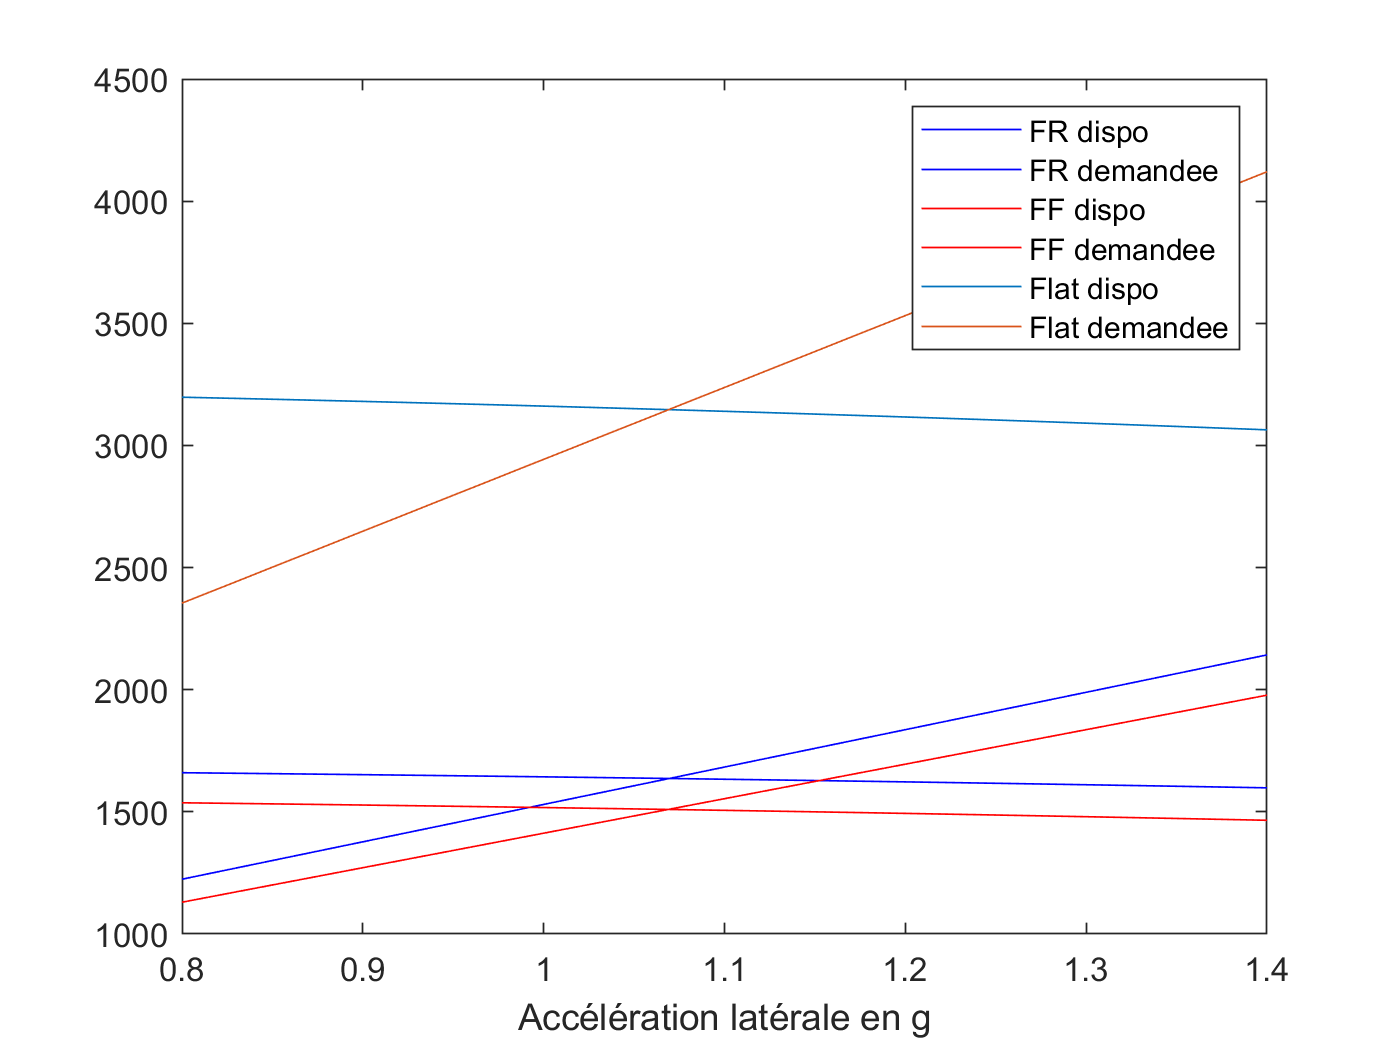

Kav=1;
Kar=0;
A=[0.8:0.01:1.4];
n=length(A);
Fr_req=0.52*9.81*W*A;
Ff_req=0.48*9.81*W*A;
F=force_lat(Kav,Kar,A);
FR=F(1:n);
FF=F(n+1:2*n);
plot(A,FR,'b',A,Fr_req,'b-',A,FF,'r',A,Ff_req,'r-',A,FR+FF,A,Fr_req+Ff_req)
xlabel('Accélération latérale en g')
legend('FR dispo','FR demandee','FF dispo','FF demandee','Flat dispo','Flat demandee')

Donc accélération max de 1.1 g.

function [t]=tau(FZ)
t=1.2-0.000000022*FZ.^2-0.9*0.00012*FZ;
end
function [F]=force_lat(Kav,Kar,A)
% Données
W=300;
KphiR=225*0.175/10;%29.7
KphiF=225*0.175/10;%36.6
l=1575;
tF=1295;
tR=1220;
WF=0.48*300;
WR=0.52*300;
h=300;
H=300;
b=l/(1+WR/WF);
a=l-b;
ZRR=50.67;
ZRF=36.44;
dWF=A.*(W/tF)*(H*(KphiF+Kav)./(KphiF+Kav+KphiR+Kar)+b*ZRF/l);
dWR=A.*(W/tR)*(H*(KphiR+Kar)./(KphiF+Kav+KphiR+Kar)+a*ZRR/l);
WFO=WF/2+dWF;
WFI=WF/2-dWF;
WRO=WR/2+dWR;
WRI=WR/2-dWR;
RF=9.81*WFO.*tau(9.81*WFO)+9.81*WFI.*tau(9.81*WFI);
RR=9.81*WRO.*tau(9.81*WRO)+9.81*WRI.*tau(9.81*WRI);
F=[RR,RF];
end